global st nuts rivets

% Find lowest significant point
input('Select the lowest point of significant values. [Press return when done].','s');
current=reshape(spm_orthviews('pos'),1,3)

current =   -43.8150  -67.5481   21.9075


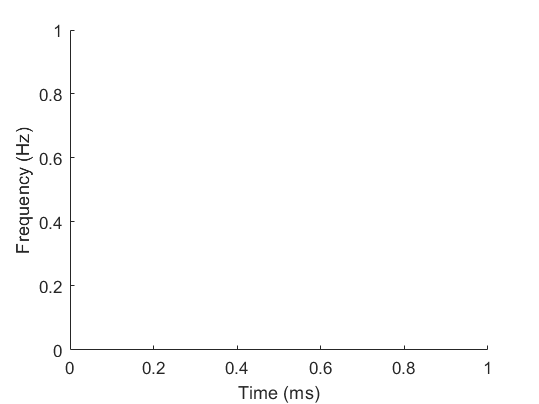

nut_reposition(nut_coordtfm(current,st.vols{1}.premul))
% save and crop image
fh = findobj( 'Type', 'Figure');
for i=1:length(fh)
    if contains(fh(i).Name,'SPM')
        Sp=i
    end
end
input('Make Sure youre clicking on the Axial View. [Press return when done].','s');
F = getframe(fh(1).CurrentAxes);

Image = frame2im(F);
imwrite(Image, 'Image.jpg')
i=''


i =

  0×0 empty char array



while( isequal(j,''))
    print('hi')
    j=input('type 1 to stop once youve reached the final snap, otherwise, press enter','s');
    if (j~=1)
        current(3)=current(3)+8
        nut_reposition(nut_coordtfm(current,st.vols{1}.premul))
        F = getframe(fh(1).CurrentAxes);
        Image = frame2im(F);
        cn=split(pwd,'\');
        cn=cn(end)
        imagename=append(cn,num2str(current(3)),'.jpg')
        imwrite(Image, imagename')
    end
end
%spm_orthviews('Xhairs','off')
